# 繪圖軟體應用 第13周(12/4)

## CH10 字串與數字處理

clear;clc
str = ['m' 'a' 't' 'l' 'a' 'b']

str = 'matlab'

ischar(str)

ans = logical
   1


### ASCII

ascii = double(str) % str的位置碼

ascii =    109    97   116   108    97    98


char(ascii) %把ascii碼轉換為字元

ans = 'matlab'

str2 = str + 10

str2 =    119   107   126   118   107   108



str3 = '00011011'

str3 = '00011011'

v = str3-48 %

v =      0     0     0     1     1     0     1     1


double('0')

ans = 48

char(v+48)

ans = '00011011'


whos

  Name       Size            Bytes  Class     Attributes

  ans        1x8                16  char                
  ascii      1x6                48  double              
  str        1x6                12  char                
  str2       1x6                48  double              
  str3       1x8                16  char                
  v          1x8                64  double              




str4 = '一個中文字佔兩個位元組'

str4 = '一個中文字佔兩個位元組'

whos

  Name       Size            Bytes  Class     Attributes

  ans        1x8                16  char                
  ascii      1x6                48  double              
  str        1x6                12  char                
  str2       1x6                48  double              
  str3       1x8                16  char                
  str4       1x11               22  char                
  v          1x8                64  double              



### 字串陣列

season = ['spring';'summer';'autumn';'winter']

season = 4×6 char array
    'spring'
    'summer'
    'autumn'
    'winter'


whos season

  Name        Size            Bytes  Class    Attributes

  season      4x6                48  char               



a = season(1:5)

a = 'ssawp'


month = ['January ';'February';'March   ']

month = 3×8 char array
    'January '
    'February'
    'March   '


str5 = deblank(month(3,:)) %去掉第三列後的空格字元

str5 = 'March'

whos s

### 字串處理函數

strcmp(str1,str2) 比較字串是否相等(邏輯)

strncmp(str1,str2,n) 比較str1和str2在第n個位置的字元是否相同

findstr(str,s) 

strrep(str,s1,s2) 將字串str裡的s1替換成s2

strtok(str,token) 將字串str裡token字串後的字串刪除

strvcat(str1,str2) 將字串垂直排列

clear;clc
b1 = upper('Happy Xmas')

b1 = 'HAPPY XMAS'

b2 = strcmp('Hello','Kitty') %我們不一樣

b2 = logical
   0


findstr('matlab','t')

ans = 3

strtok(b1,'M')

ans = 'HAPPY X'

### 字串求值

eval('32+6') %可執行字串

ans = 38

eval(['x' '1' '=' 'sind(30)'])

x1 = 0.5000

### 用for來運用eval( )

for i=1:3
    eval(['sqrt' num2str(i) '=' 'sqrt(i)'])
end

sqrt1 = 1

sqrt2 = 1.4142

sqrt3 = 1.7321

###  字串與數值的轉換

int2str(x)

num2str(x)

num2str(x,n) 以n位數表示

mat2str2(x)

str2num(x)

clear;clc
int2str([12.3 52.8 49.6]) %四捨五入轉成整數

ans = '12  53  50'

### 不同數字系統的轉換

dec2bin(x)

dec2bin(x,n)

dec2base(x,base)

base2dec(str,base)

c = dec2bin([23 56 15 49 72 61],8)

c = 6×8 char array
    '00010111'
    '00111000'
    '00001111'
    '00110001'
    '01001000'
    '00111101'


bin2dec(c)

ans =     23
    56
    15
    49
    72
    61


reshape(bin2dec(c),2,3)

ans =     23    15    72
    56    49    61


位元處理函數

% 

## CH11 其他資料型態

## (結構structure、多質陣列cell array)

### 結構(structure) : 

- 結構名稱

- 欄位名稱

clear;clc
% 建立結構student
% 結構名稱.欄位名稱
student.name = 'Tom';
student.id = 'A781035';
student.score = [11 13 9 11 11];
strct = student 

strct = struct with fields:
     name: 'Tom'
       id: 'A781035'
    score: [11 13 9 11 11]



size(student)

ans =      1     1



student(2).name = 'Jaden'; %第2位同學
student(2).id = 'B781035';
student(2).score = [15 15 15 15 15];
strct2 = student

strct2 = 1×2 struct array with fields:
    name
    id
    score


s = struct('欄位1','值1','欄位2','值2')

student(3) = struct('name','Hannah','id','C781035',...
    'score',[15 14 10 13 12]);
strct3 = student

strct3 = 1×3 struct array with fields:
    name
    id
    score


擷取

[student.name]

ans = 'TomJadenHannah'

[student.id]

ans = 'A781035B781035C781035'

[student.score]

ans =     11    13     9    11    11    15    15    15    15    15    15    14    10    13    12


cat(1,student.id) %一維方向合併ID

ans = 3×7 char array
    'A781035'
    'B781035'
    'C781035'


編修結構陣列的欄位

fieldnames(student) %查詢結構內的所有欄位

ans = 3×1 cell array
    {'name' }
    {'id'   }
    {'score'}


student2 = student;
student2(1).age = 19

student2 = 1×3 struct array with fields:
    name
    id
    score
    age


運算

st(1) = struct('name','Tom','score',[67 89]);
st(2) = struct('name','Jay','score',[74 92]);
isstruct(st) %查詢st是否為一個結構陣列

ans = logical
   1


isfield(st,'score') %結構陣列st是否有欄位score

ans = logical
   1


for : 

if isstruct(st)
    avg=0;

A = 1×3 cell array
    {'abc'}    {[1234]}    {3×3 double}


    for i = 1:length(st) 

sizeA =      1     3


        if avg < mean(st(i).score)

C = 3×3 cell array
    {'abc'}    {[1234]}    {3×3 double}
    {'abc'}    {[1234]}    {3×3 double}
    {'abc'}    {[1234]}    {3×3 double}


            avg = mean(st(i).score);
            num=i;
        end
    end
    fprintf('%s分數最高\n',st(num).name)

D = 1×3 cell array
    {'cde'}    {[5678]}    {4×4 double}


    fprintf('平均成績為%6.2f\n',avg)
else 
    disp('st不是一個結構陣列')
end

### Cell Array

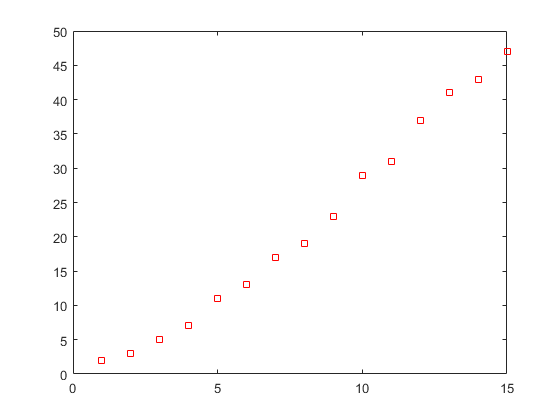

clear;clc
A = {'abc',1234,magic(3)}
sizeA = size(A)
C = repmat(A,3,1) %重複多質陣列A


D{1,1} = 'cde';
D{1,2} = 5678;

pl =     3.4036   -5.3619


D{1,3} = magic(4);

fl =    -1.9583    1.4452    4.8488    8.2524   11.6560   15.0595   18.4631   21.8667   25.2702   28.6738   32.0774   35.4810   38.8845   42.2881   45.6917


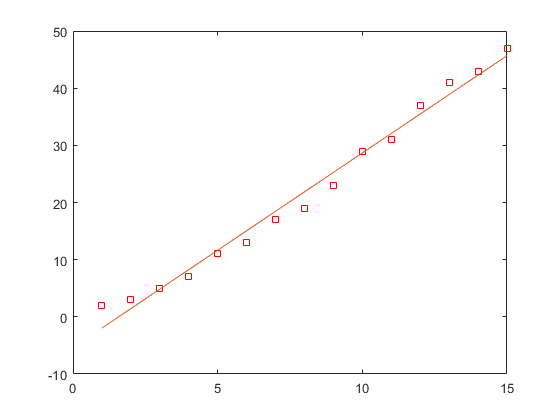

D

## CH13 曲線擬合與插值法

### 曲線擬合 : 最小平方法

polyfit(x,y,n)  以x、y向量進行n階多項式擬合，回應一個列向量

polyval(p,a)

clear;clc

p2 =     0.0907    1.9517   -1.2484


%以多項式來擬合小於50的質數所組成的資料點

f2 =     0.7941    3.0181    5.4235    8.0104   10.7788   13.7287   16.8600   20.1729   23.6672   27.3430   31.2002   35.2390   39.4592   43.8609   48.4441


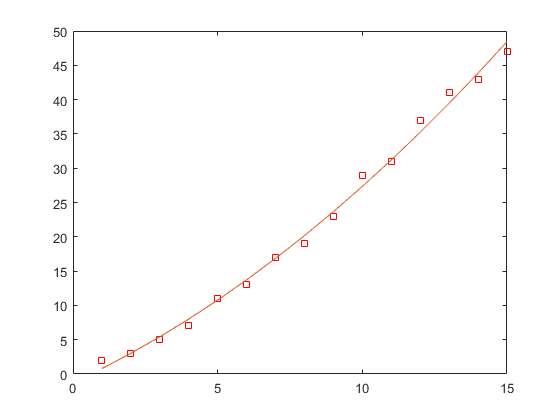

y = primes(50);

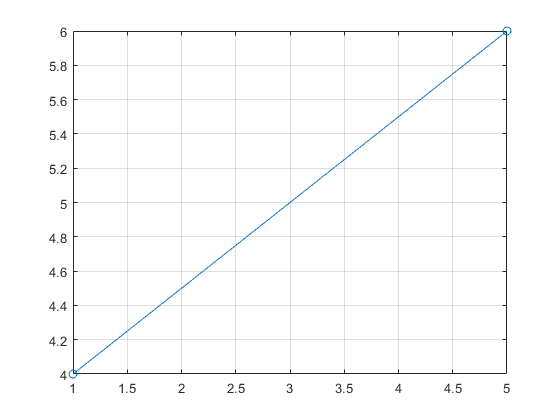

x = 1:length(y);
plot(x,y,'Sr')


pl = polyfit(x,y,1) % 擬合結果 : 3.4036x - 5.3619

ans = 4

fl = polyval(pl,x) %計算多項式pl(x)的值
plot(x,y,'sr',x,fl,'-')

ans = 4.5000


p2 = polyfit(x,y,2) %二階多項式擬合結果:
f2 = polyval(p2,x)
plot(x,y,'sr',x,f2,'-')

### 一維插值法(interpolation) : interp1

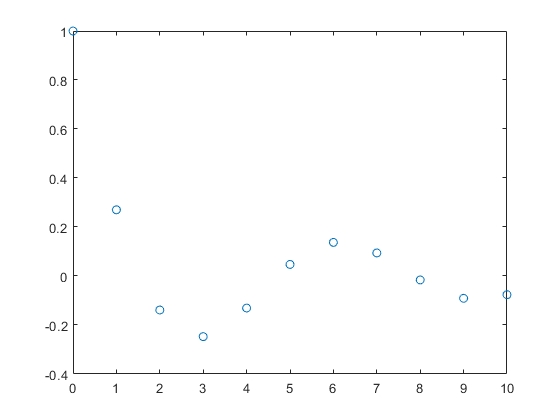

clear;clc

plot([1 5],[4 6],'-o');grid on
interp1([1 5],[4 6],2,'nearest') 
%以鄰近點插值法求解在x=2時的內插值

y0 =     1.0000    0.2702    0.2702   -0.1387   -0.1387   -0.2475   -0.2475   -0.1307   -0.1307    0.0473    0.0473    0.1372    0.1372    0.0942    0.0942   -0.0162   -0.0162   -0.0911   -0.0911   -0.0763   -0.0763


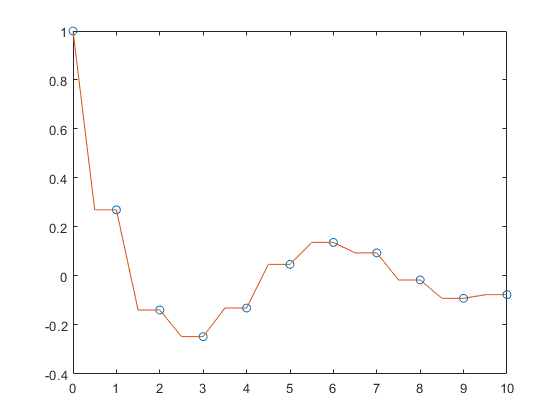

interp1([1 5],[4 6],2,'linear')

%以線性插值法求解在x=2時的內插值


y1 =     1.0000    0.6351    0.2702    0.0657   -0.1387   -0.1931   -0.2475   -0.1891   -0.1307   -0.0417    0.0473    0.0922    0.1372    0.1157    0.0942    0.0390   -0.0162   -0.0536   -0.0911   -0.0837   -0.0763


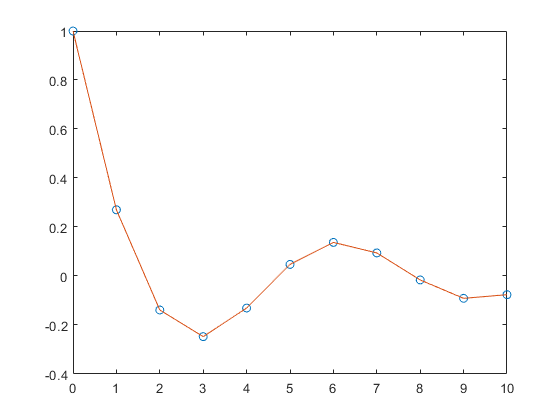

x= 0:10;

y= cos(x)./(1+x);
plot(x,y,'o')

x1 = 0:0.5:10;
y0 = interp1(x,y,x1,'nearest')
plot(x,y,'o',x1,y0,'-')

y1 = interp1(x,y,x1,'linear')
plot(x,y,'o',x1,y1,'-')

### 二維插值法: interp2

### 二維的散佈點內插: griddata

使用時機 : 二維資料點並不是剛好位於網格點上面

## CH17 檔案處理

### 寫入與寫出工作區內的變數

clear;clc
% 建立結構student
% 結構名稱.欄位名稱
student.name = 'Tom';

strct = struct with fields:
     name: 'Tom'
       id: 'A781035'
    score: [11 13 9 11 11]


student.id = 'A781035';
student.score = [11 13 9 11 11];
strct = student 
size(student);

save tt2 student %把student存為tt2.mat

  Name         Size            Bytes  Class     Attributes

  ans          1x2                16  double              
  strct        1x1               588  struct              
  student      1x1               588  struct              




load tt2.mat

score =     11    13     9    11    11


whos

score = student.score
save tt2.dat score -ascii %把score存為ascii檔案tt2.dat

### 以逗號隔開(CSV)

clear;clc

### 以特定符號隔開(dlm)